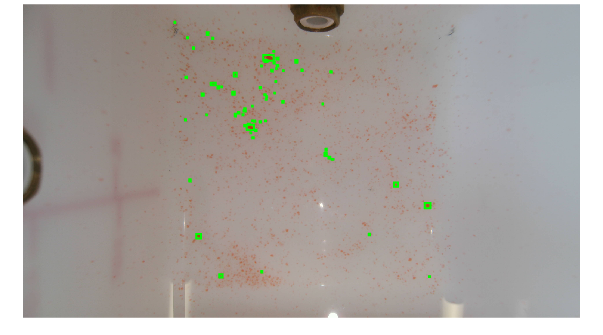

clc; clear; close all;

% Load image
image_path = 'original_image.png';
img = imread(image_path);

% Convert image to HSV color space
hsv_img = rgb2hsv(img);

% Define red color thresholds
lower_red1 = [0, 0.5, 0.2];
upper_red1 = [0.05, 1, 1];
lower_red2 = [0.9, 0.5, 0.2];
upper_red2 = [1, 1, 1];

% Create masks for red regions
mask1 = (hsv_img(:,:,1) >= lower_red1(1)) & (hsv_img(:,:,1) <= upper_red1(1)) & ...
        (hsv_img(:,:,2) >= lower_red1(2)) & (hsv_img(:,:,2) <= upper_red1(2)) & ...
        (hsv_img(:,:,3) >= lower_red1(3)) & (hsv_img(:,:,3) <= upper_red1(3));
mask2 = (hsv_img(:,:,1) >= lower_red2(1)) & (hsv_img(:,:,1) <= upper_red2(1)) & ...
        (hsv_img(:,:,2) >= lower_red2(2)) & (hsv_img(:,:,2) <= upper_red2(2)) & ...
        (hsv_img(:,:,3) >= lower_red2(3)) & (hsv_img(:,:,3) <= upper_red2(3));
    
red_mask = mask1 | mask2;

% Remove noise using morphological operations
se = strel('disk', 2);
red_mask = imopen(red_mask, se);

% Find and draw contours
props = regionprops(red_mask, 'BoundingBox');
figure;
imshow(img);
hold on;
for i = 1:length(props)
    rectangle('Position', props(i).BoundingBox, 'EdgeColor', 'g', 'LineWidth', 2);
end
hold off;

title('Detected Red Clots');